clc;
clear;

sensor = readmatrix(['../sensor_data_0_cls.csv']);
pred_vec = readmatrix(['../force_np_cls.csv']);
pred_zero = readmatrix(['../zero_v_cls.csv']);
pred_mul = readmatrix(['../simple_mtply_cls.csv']);

pred_vec = pred_vec.';
pred_zero = pred_zero.';
pred_mul = pred_mul.';

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_3_16.csv';
% network = '_seal_pred_filtered_torque_si_3_15.csv';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

arm = 'psm3_fena';


%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];
    

%       joint_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/joints/'];
%       jacobian_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/jacobian/'];
%       torque_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', test_folder, '/', arm, '/', data, '/', 'lstm', network];
      joint_path = ['dvrk-3-16-perfect/csv/', test_folder, '/', data, '/joints/'];
      jacobian_path = ['dvrk-3-16-perfect/csv/', test_folder, '/', data, '/jacobian/'];
      torque_path = ['dvrk-3-16-perfect/csv/', test_folder, '/', data, '/', 'lstm', network];

joint_data = readmatrix([joint_path, 'interpolated_all_joints.csv']);
jacobian_data = readmatrix([jacobian_path, 'interpolated_all_jacobian.csv']);
torque_data = readmatrix(torque_path);

jacobian = jacobian_data(:, 2:37).';
jacobian = reshape(jacobian,[6,6,length(jacobian)]);
jacobian = permute(jacobian, [2 1 3]);

jacobian(:,:,1)

ans =     0.0000    0.0000   -0.2485   -0.0000    0.0722    0.0723
   -0.0000   -0.0000    0.3843   -0.0000   -0.0546    0.0831
   -0.0000    0.0000   -0.8892    0.0000   -0.0438    0.0157
    0.0000   -0.9631         0   -0.2485    0.6500   -0.7185
   -1.0000    0.0000         0    0.3843    0.7467    0.5435
    0.0000    0.2691         0   -0.8892    0.1411    0.4339



fs_pred_torque = torque_data(:,2:7).';
% fs_pred_torque = fs_pred_torque(:, 1:length(fs_pred_torque)/2);
measured_torque = joint_data(1:length(fs_pred_torque),14:19).';
jacobian = jacobian(:,:,1:length(fs_pred_torque));

fs_diff = measured_torque - fs_pred_torque;
fs_force = zeros(6,length(fs_pred_torque));



angle = pi/2;
Ra = [cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1];
Rz = [-1.0000 0 0; 0 -0.7071 -0.7071; 0 -0.7071 0.7071];
% Rz = [cos(angle) 0 sin(angle); 0 1 0; -sin(angle) 0 cos(angle)]  % Ry actually
% Rz = [1 0 0; 0 cos(angle) -sin(angle);0 sin(angle) cos(angle)]  % Rx actually
det(Rz);
another_angle = -1/4*pi;
rotation = [cos(another_angle) -sin(another_angle) 0; sin(another_angle) cos(another_angle) 0; 0 0 1];

for i = 1:length(fs_pred_torque)
    fs_force(:,i) = inv(jacobian(:,:,i).') * (fs_diff(:,i));
    fs_force(1:3, i) = rotation * fs_force(1:3, i);
    pred_vec(1:3, i) = rotation * pred_vec(1:3, i);
    pred_zero(1:3, i) = rotation * pred_zero(1:3, i);
    pred_mul(1:3, i) =  pred_mul(1:3, i);
end

fs_force = fs_force.';
pred_vec = pred_vec.';
pred_zero = pred_zero.';
pred_mul = pred_mul.';

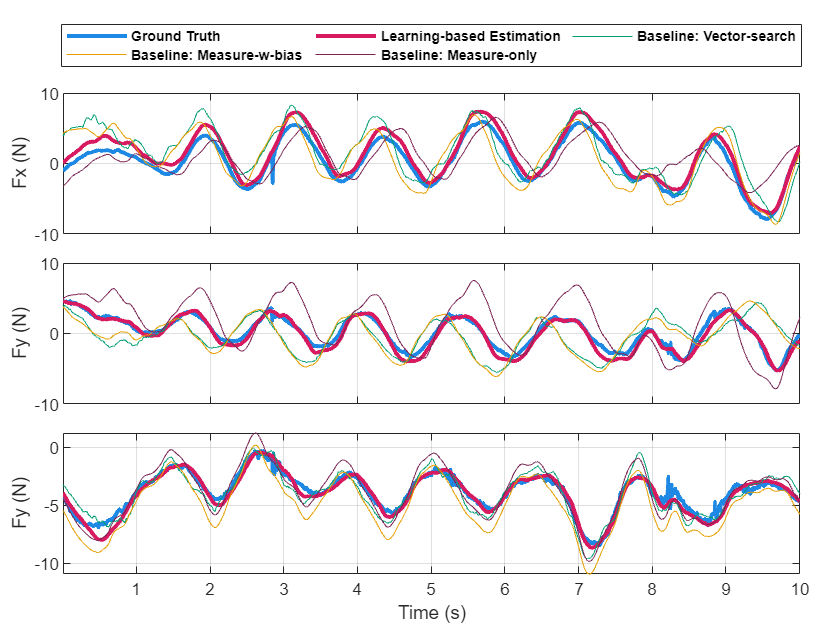


% real_force_path = ['../../dvrk_colon_9_26/bilateral_free_space_sep_27/', 'test/', arm, '/', 'sensor/'];
real_force_path = ['dvrk-3-16-perfect/csv/', 'sensor/'];
real_force_data = readmatrix([real_force_path, 'interpolated_all_sensor.csv']);
real_force = real_force_data(1:length(fs_pred_torque),2:7);


windowSize = 30; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

fs_force_filt = filter(b,a,fs_force);

fs_force_unfilt = fs_force;

fs_force = filter(b,a,fs_force);
pred_vec = filter(b,a,pred_vec);
pred_zero = filter(b,a,pred_zero);
pred_mul = filter(b,a,pred_mul);

loss_x = mean(sqrt(mean( (fs_force(:,1) - real_force(:,1)).^2 )));
loss_y = mean(sqrt(mean( (fs_force(:,2) - real_force(:,2)).^2 )));
loss_z = mean(sqrt(mean( (fs_force(:,3) - real_force(:,3)).^2 )));

loss_x_unf = mean(sqrt(mean( (fs_force_unfilt(:,1) - real_force(:,1)).^2 )));
loss_y_unf = mean(sqrt(mean( (fs_force_unfilt(:,2) - real_force(:,2)).^2 )));
loss_z_unf = mean(sqrt(mean( (fs_force_unfilt(:,3) - real_force(:,3)).^2 )));


[minSix, maxSix] = bounds(fs_force(:,1));
boundX = abs(maxSix - minSix);
[minSiy, maxSiy] = bounds(fs_force(:,2));
boundY = abs(minSiy - maxSiy);
[minSiz, maxSiz] = bounds(fs_force(:,3));
boundZ = abs(maxSiz - minSiz);

figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

% title(tcl, sprintf('dVRK Classic Tool Tip Cartesian Force \n Ground Truth vs. Baselines vs. Learning-based Estimation'), fontweight='Bold')


startT = 60/0.005;
endT = 70/0.005;

nexttile
plot(0.005*(1:length(real_force(startT:endT,1))), real_force(startT:endT,1), color = '#1E88E5', LineWidth=2)
hold on
% title(sprintf('Fx, RMSE = %.4f', loss_x))
plot(0.005*(1:length(real_force(startT:endT,1))), fs_force(startT+10:endT+10,1), color ='#D81B60', LineWidth=2)
plot(0.005*(1:length(real_force(startT:endT,1))), pred_vec(startT:endT,1), color ='#009E73')
plot(0.005*(1:length(real_force(startT:endT,1))), pred_zero(startT:endT,1), color ='#E69F00')
plot(0.005*(1:length(real_force(startT:endT,1))), pred_mul(startT:endT,1), color ='#7B2655')
xticklabels([])
xlim tight
% xlabel('Time (s)')
ylabel('Fx (N)')
grid on

legend('Ground Truth', 'Learning-based Estimation', 'Baseline: Vector-search', 'Baseline: Measure-w-bias', 'Baseline: Measure-only' ...
    , fontsize = 7, Location='northoutside', fontweight='Bold', Orientation='horizon', NumColumns=3)

hold off

nexttile
plot(0.005*(1:length(real_force(startT:endT,2))), real_force(startT:endT,2), color = '#1E88E5', LineWidth=2)
hold on
% title(sprintf('Fy, RMSE = %.4f', loss_y))
plot(0.005*(1:length(real_force(startT:endT,2))), fs_force(startT+10:endT+10,2), color ='#D81B60', LineWidth=2)
plot(0.005*(1:length(real_force(startT:endT,2))), pred_vec(startT:endT,2), color ='#009E73')
plot(0.005*(1:length(real_force(startT:endT,2))), pred_zero(startT:endT,2), color ='#E69F00')
plot(0.005*(1:length(real_force(startT:endT,2))), pred_mul(startT:endT,2), color ='#7B2655')
xticklabels([])
xlim tight
% xlabel('Time (s)')
ylabel('Fy (N)')
grid on
hold off

nexttile
plot(0.005*(1:length(real_force(startT:endT,3))), real_force(startT:endT,3), color = '#1E88E5', LineWidth=2)
hold on
% title(sprintf('Fz, RMSE = %.4f', loss_z))
plot(0.005*(1:length(real_force(startT:endT,3))), fs_force(startT+5:endT+5,3), color ='#D81B60', LineWidth=2)
plot(0.005*(1:length(real_force(startT:endT,3))), pred_vec(startT:endT,3), color ='#009E73')
plot(0.005*(1:length(real_force(startT:endT,3))), pred_zero(startT:endT,3), color ='#E69F00')
plot(0.005*(1:length(real_force(startT:endT,3))), pred_mul(startT:endT,3), color ='#7B2655')
xlim tight
xlabel('Time (s)')
ylabel('Fy (N)')
grid on


hold off